# Euler Parameters

Mengasumsikan bahwa $\phi$ adalah rotasi sudut dari local frame B(O$xyz
$) terhadap $\hat{u}$ = $u_1 \hat{I}$ + $u_2 \hat{J}$ + $u_3 \hat{K}$yang berhubungan dengan global frame G(OXYZ). Wujud rotasi axis merepresentasikan Teorema Euler tentang rotasi tubuh kaku yaitu : *Secara umum pemindahan tubuh kaku dengan satu titik tertentu adalah rotasi terhadap beberapa axis *Untuk menemukan rotasi dari axis dan sudut, kita memperkenalkan Euler Parameters.

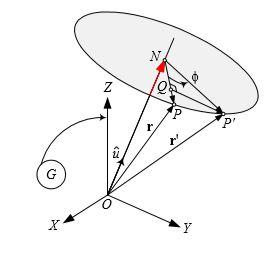

Gambar diatas menunjukkan bahwa sebuah titik P di tubuh kaku dengan vektor posisi r, dan unit vektor / vektor satuan $\hat{u}$ sepanjang sumbu rotasi ON di global frame. Titik bergerak ke P' dengan vektor posis r' setelah sebuah rotasi aktif sebesar $\phi$ terhadap $\hat{u}$. untuk memperoleh hubungan antara r dan r', kita dapat mengekspresikan r' sebagai persamaan vektor berikut : 

r' = ON + NQ + QP'

Mencari Nilai ON :

Awalnya, menginisialisasi $e\;\textrm{yang}\;\textrm{berisi}\;$$e_1$, $e_2$, $e_3$

syms r phi e1 e2 e3 Eo
e= sqrt(e1^2+e2^2+e3^2)

$$e = \sqrt{{e_{1}}^{2}+{e_{2}}^{2}+{e_{3}}^{2}}$$

Menginisialiasi matriks Identitas yaitu: $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$

I= [1 0 0; 0 1 0; 0 0 1]

I =      1     0     0
     0     1     0
     0     0     1


Menginisialisasi rumus $\hat{u}$ sebagai berikut:

u = sqrt(cos(phi))

$$u = \sqrt{\cos\left(\varphi \right)}$$

ON = $\left(r\;x\;\hat{u} \right)\hat{\;u}$

= $r\;\cos \;\phi$

ON = r*u*u

$$ON = r\,\cos\left(\varphi \right)$$

Berdasarkan rumus Trigonometri cos$\phi$ = ${2\;\mathrm{cos}}^2 \frac{\phi }{2}-1$ dapat ditentukan bahwa ON:

eqn = subs(ON, cos(phi), 2*cos(phi/2)*cos(phi/2)-1)

$$eqn = r\,\left(2\,{\cos\left(\frac{\varphi }{2}\right)}^{2}-1\right)$$

Berdasarkan sifat Euler Parameters nilai $e_0 ={\;\cos }^2 \frac{\phi }{2}\;$

eqn = subs(eqn, cos(phi/2),Eo)

$$eqn = r\,\left(2\,{\mathrm{Eo}}^{2}-1\right)$$

Maka dari turunan persamaan diatas, dapat didapatkan matriks ON sebagai berikut:

    ON = ($\left.{e_0 }^2 -e^2 \right)I$

= $\left({e_0 }^2 -e_1^2 -e_2^2 -e_3^2 \;\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$

= $\left\lbrack \begin{array}{ccc}
{e_0 }^2 -e_1^2 -e_2^2 -e_3^2  & 0 & 0\\
0 & {e_0 }^2 -e_1^2 -e_2^2 -e_3^2  & 0\\
0 & 0 & {e_0 }^2 -e_1^2 -e_2^2 -e_3^2 
\end{array}\right\rbrack$

ON = subs(eqn, 2*Eo^2-1, ((Eo^2-e^2)*I))

$$ON = \left(\begin{array}{ccc} -r\,\left(-{\mathrm{Eo}}^{2}+{e_{1}}^{2}+{e_{2}}^{2}+{e_{3}}^{2}\right) & 0 & 0\\ 0 & -r\,\left(-{\mathrm{Eo}}^{2}+{e_{1}}^{2}+{e_{2}}^{2}+{e_{3}}^{2}\right) & 0\\ 0 & 0 & -r\,\left(-{\mathrm{Eo}}^{2}+{e_{1}}^{2}+{e_{2}}^{2}+{e_{3}}^{2}\right) \end{array}\right)$$

Mencari nilai NQ :

Menginisialisasi rumus komponen dari Euler Parameters $\hat{u} =\frac{e}{\sin \;\frac{\phi }{2}}$

syms ee
u = ee/sin(phi/2)

$$u = \frac{\mathrm{ee}}{\sin\left(\frac{\varphi }{2}\right)}$$

Menginisialisasi rumus Trigonometri $1-\cos \;\phi =2\;\sin^2 \frac{\phi }{2}$

smcosphi = 2*sin(phi/2)*sin(phi/2)

$$smcosphi = 2\,{\sin\left(\frac{\varphi }{2}\right)}^{2}$$

NQ = $\hat{u} \;x\;\left(r\;x\;\hat{u} \right)$ cos$\phi$

= [$r-\left(r\;\hat{u} \right)\hat{u}$] cos$\phi$

= $\left(1-\cos \;\phi \right)$$\left(r\;\hat{u} \right)\hat{u}$

NQ = (smcosphi)*(u*r)*u

$$NQ = 2\,{\mathrm{ee}}^{2}\,r$$

Menginisalisasi matriks dari komponen Euler Parameters $e=\left\lbrack \begin{array}{c}
e_1 \\
e_2 \\
e_3 
\end{array}\right\rbrack$

e= [e1; e2; e3]

$$e = \left(\begin{array}{c} e_{1}\\ e_{2}\\ e_{3} \end{array}\right)$$

Maka NQ diperoleh sebagai berikut: 

NQ = $2\;e\;e^T$

= 2 $\left\lbrack \begin{array}{c}
e_1 \\
e_2 \\
e_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
e_1  & e_2  & e_3 
\end{array}\right\rbrack$

NQ = subs(NQ, ee*ee, (e*transpose(e)))

$$NQ = \left(\begin{array}{ccc} 2\,{e_{1}}^{2}\,r & 2\,e_{1}\,e_{2}\,r & 2\,e_{1}\,e_{3}\,r\\ 2\,e_{1}\,e_{2}\,r & 2\,{e_{2}}^{2}\,r & 2\,e_{2}\,e_{3}\,r\\ 2\,e_{1}\,e_{3}\,r & 2\,e_{2}\,e_{3}\,r & 2\,{e_{3}}^{2}\,r \end{array}\right)$$

Mencari QP' :

Sebelumnya harus menginisialisasi rumus-rumus penunjang penyelesaian QP seperti: 

$\sin \phi =2\;\sin \;\frac{\phi }{2}$ cos $\frac{\phi }{2}$ 

sinphi = 2*sin(phi/2)*cos(phi/2)

$$sinphi = 2\,\cos\left(\frac{\varphi }{2}\right)\,\sin\left(\frac{\varphi }{2}\right)$$

$\tilde{e} \;\textrm{adalah}\;\textrm{matriks}\;\textrm{skew}-\textrm{symmetric}\;\textrm{yang}\;\textrm{berhubungan}\;\textrm{dengan}\;e\ldotp$ Rumus $\tilde{e} \;$telah diajarkan dan didapat pada bab Angle-Axis Rotation yaitu $\tilde{e} =R_B^G -{R_B^G }^T$

eSkew = [0 -e3 e2; e3 0 -e1; -e2 e1 0]

$$eSkew = \left(\begin{array}{ccc} 0 & -e_{3} & e_{2}\\ e_{3} & 0 & -e_{1}\\ -e_{2} & e_{1} & 0 \end{array}\right)$$

= $\left(\hat{u} \;x\;r\right)$sin $\phi$

QP = (u*r)*sinphi

$$QP = 2\,\mathrm{ee}\,r\,\cos\left(\frac{\varphi }{2}\right)$$

Berdasarkan rumus Euler Parameters $e_0 ={\;\cos }^2 \frac{\phi }{2}$

eqn = subs(QP, cos(phi/2), Eo)

$$eqn = 2\,\mathrm{Eo}\,\mathrm{ee}\,r$$

Maka matriks QP diperoleh sebagai berikut:

QP = subs(eqn, ee, eSkew)

$$QP = \left(\begin{array}{ccc} 0 & -2\,\mathrm{Eo}\,e_{3}\,r & 2\,\mathrm{Eo}\,e_{2}\,r\\ 2\,\mathrm{Eo}\,e_{3}\,r & 0 & -2\,\mathrm{Eo}\,e_{1}\,r\\ -2\,\mathrm{Eo}\,e_{2}\,r & 2\,\mathrm{Eo}\,e_{1}\,r & 0 \end{array}\right)$$

Mencari nilai r' = ON + NQ + QP'

rG = ON + NQ + QP

$$gRb = \begin{array}{l} \left(\begin{array}{ccc} 2\,{e_{1}}^{2}\,r-\sigma_{1} & 2\,e_{1}\,e_{2}\,r-2\,\mathrm{Eo}\,e_{3}\,r & 2\,\mathrm{Eo}\,e_{2}\,r+2\,e_{1}\,e_{3}\,r\\ 2\,\mathrm{Eo}\,e_{3}\,r+2\,e_{1}\,e_{2}\,r & 2\,{e_{2}}^{2}\,r-\sigma_{1} & 2\,e_{2}\,e_{3}\,r-2\,\mathrm{Eo}\,e_{1}\,r\\ 2\,e_{1}\,e_{3}\,r-2\,\mathrm{Eo}\,e_{2}\,r & 2\,\mathrm{Eo}\,e_{1}\,r+2\,e_{2}\,e_{3}\,r & 2\,{e_{3}}^{2}\,r-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r\,\left(-{\mathrm{Eo}}^{2}+{e_{1}}^{2}+{e_{2}}^{2}+{e_{3}}^{2}\right) \end{array}$$


$$r^G =R_B^G \;x\;r^B$$


$R_B^G$ = $\frac{r^G }{r^B }$

dimana, $r^{\prime }$ mempresentasikan $r^G \;$dan r mempresentasikan $r^B$

gRb = simplify(rG/r)

$$gRb = \left(\begin{array}{ccc} {\mathrm{Eo}}^{2}+{e_{1}}^{2}-{e_{2}}^{2}-{e_{3}}^{2} & 2\,e_{1}\,e_{2}-2\,\mathrm{Eo}\,e_{3} & 2\,\mathrm{Eo}\,e_{2}+2\,e_{1}\,e_{3}\\ 2\,\mathrm{Eo}\,e_{3}+2\,e_{1}\,e_{2} & {\mathrm{Eo}}^{2}-{e_{1}}^{2}+{e_{2}}^{2}-{e_{3}}^{2} & 2\,e_{2}\,e_{3}-2\,\mathrm{Eo}\,e_{1}\\ 2\,e_{1}\,e_{3}-2\,\mathrm{Eo}\,e_{2} & 2\,\mathrm{Eo}\,e_{1}+2\,e_{2}\,e_{3} & {\mathrm{Eo}}^{2}-{e_{1}}^{2}-{e_{2}}^{2}+{e_{3}}^{2} \end{array}\right)$$